# Fault Detection

Pieter Leon van den Berg

22684166

20 October 2022

Final Year Project (C) 478

Supervisor: Dr Cripwell

### Setup

clear;
clc;

## Settings

### Data export

SAVE_IMAGES = true;                             % Save the generated graphs
SAVE_DATA   = true;                             % Save the generated data

### PCA

NUMBER_OF_PRINCIPLE_COMPONENTS_TO_USE = 11;     % Number of principle components to use for the reduced subspace 

## PCA

### Read the training data to use for PCA

TRAINING_DATA = readtable('fault_detection\data\normal_training.csv')

TRAINING_DATA = 24001×19 table
    Time    c_LO_measured    c_RE_measured    f_PLSP_measured    f_PLSS_measured    f_LO_measured    f_LE_measured    c_PLS_measured    c_LE_measured    c_RaffP_measured    c_RaffS_measured    c_BO_measured    v_LO_control    v_LO_valve    v_LE_control    v_LE_valve    v_LO_state    v_LE_state    process_state
    ____    _____________    _____________    _______________    _______________    _____________    _____________    ______________    _____________    ________________

### Read the timeseries

% Read the time of the training data
training_time = TRAINING_DATA.Time;

% Read the timeseries variables of the training data
training_c_LO    = TRAINING_DATA.c_LO_measured;
training_c_RE    = TRAINING_DATA.c_RE_measured;
training_f_PLSP  = TRAINING_DATA.f_PLSP_measured;
training_f_PLSS  = TRAINING_DATA.f_PLSS_measured;
training_f_LO    = TRAINING_DATA.f_LO_measured;
training_f_LE    = TRAINING_DATA.f_LE_measured;
training_c_PLS   = TRAINING_DATA.c_PLS_measured;
training_c_LE    = TRAINING_DATA.c_LE_measured;
training_c_RaffP = TRAINING_DATA.c_RaffP_measured;
training_c_RaffS = TRAINING_DATA.c_RaffS_measured;
training_c_BO    = TRAINING_DATA.c_BO_measured;

% Read the process state of the training data
training_process_state = TRAINING_DATA.process_state;

### Normalizing the training data

% Determining the means of the training data
c_LO_mu    = mean(training_c_LO);
c_RE_mu    = mean(training_c_RE);
f_PLSP_mu  = mean(training_f_PLSP);
f_PLSS_mu  = mean(training_f_PLSS);
f_LO_mu    = mean(training_f_LO);
f_LE_mu    = mean(training_f_LE);
c_PLS_mu   = mean(training_c_PLS);
c_LE_mu    = mean(training_c_LE);
c_RaffP_mu = mean(training_c_RaffP);
c_RaffS_mu = mean(training_c_RaffS);
c_BO_mu    = mean(training_c_BO);

% Determining the standard deviations of the training data
c_LO_sigma    = std(training_c_LO);
c_RE_sigma    = std(training_c_RE);
f_PLSP_sigma  = std(training_f_PLSP);
f_PLSS_sigma  = std(training_f_PLSS);
f_LO_sigma    = std(training_f_LO);
f_LE_sigma    = std(training_f_LE);
c_PLS_sigma   = std(training_c_PLS);
c_LE_sigma    = std(training_c_LE);
c_RaffP_sigma = std(training_c_RaffP);
c_RaffS_sigma = std(training_c_RaffS);
c_BO_sigma    = std(training_c_BO);

% Normalize the training data
training_c_LO_normalized    = (training_c_LO    - c_LO_mu   ) ./ c_LO_sigma;
training_c_RE_normalized    = (training_c_RE    - c_RE_mu   ) ./ c_RE_sigma;
training_f_PLSP_normalized  = (training_f_PLSP  - f_PLSP_mu ) ./ f_PLSP_sigma;
training_f_PLSS_normalized  = (training_f_PLSS  - f_PLSS_mu ) ./ f_PLSS_sigma;
training_f_LO_normalized    = (training_f_LO    - f_LO_mu   ) ./ f_LO_sigma;
training_f_LE_normalized    = (training_f_LE    - f_LE_mu   ) ./ f_LE_sigma;
training_c_PLS_normalized   = (training_c_PLS   - c_PLS_mu  ) ./ c_PLS_sigma;
training_c_LE_normalized    = (training_c_LE    - c_LE_mu   ) ./ c_LE_sigma;
training_c_RaffP_normalized = (training_c_RaffP - c_RaffP_mu) ./ c_RaffP_sigma;
training_c_RaffS_normalized = (training_c_RaffS - c_RaffS_mu) ./ c_RaffS_sigma;
training_c_BO_normalized    = (training_c_BO    - c_BO_mu   ) ./ c_BO_sigma;

### Perform PCA on the training data

% Create the normalized training data matrix
training_data_array_normalized = [training_c_LO_normalized, training_c_RE_normalized, training_f_PLSP_normalized, training_f_PLSS_normalized, ...
                                  training_f_LO_normalized, training_f_LE_normalized, training_c_PLS_normalized, training_c_LE_normalized,    ...
                                  training_c_RaffP_normalized, training_c_RaffS_normalized, training_c_BO_normalized];

% Perform the PCA on the normalized training data
[PCA_coeff, training_Z, PCA_latent, PCA_tsquared, PCA_explained, PCA_mu] = pca(training_data_array_normalized);

### Setup plotting

% Line styles
line_width = 0.8;

% Colours
blue  = '#06ACE9';
white = '#FFFFFF';

### Scree plot

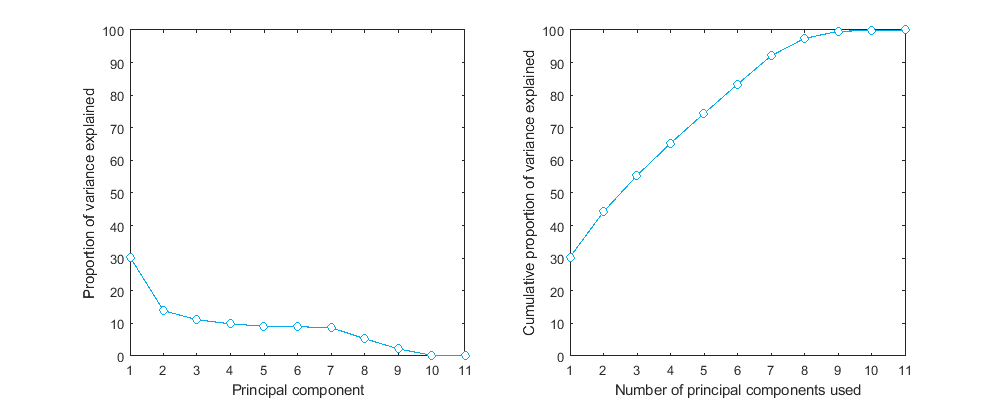

% Create the scree plot figure
figure()

% Plot the proportion of variance explained
subplot(1,2,1)
plot(PCA_explained, '-o', 'LineWidth',line_width, 'Color', blue, 'MarkerFaceColor', white, 'MarkerEdgeColor', blue, 'MarkerSize', 6)
ylabel("Proportion of variance explained")
xlabel("Principal component")
ylim([0 100])
xlim([1 11])
xticks([1, 2, 3, 4, 5, 6, 7, 8, 9, 10, 11])

% Plot the cumulative proportion of variance explained
subplot(1,2,2)
plot(cumsum(PCA_explained), '-o', 'LineWidth',line_width, 'Color', blue, 'MarkerFaceColor', white, 'MarkerEdgeColor', blue, 'MarkerSize', 6)
ylabel("Cumulative proportion of variance explained")
xlabel("Number of principal components used")
ylim([0 100])
xlim([1 11])
xticks([1, 2, 3, 4, 5, 6, 7, 8, 9, 10, 11])

% Set the plot size
fig_scree_plot = gcf;
fig_scree_plot.Position(3:4) = [1000, 400];

% Save the current figure
if (SAVE_IMAGES)
    print('fault_detection/output/PCA/scree_plot', '-dpng', '-r600')
end

### PCA loadings

% Variable labels
measured_variable_labels = categorical({'c_{LO}', 'c_{RE}', 'f_{PLSP}', 'f_{PLSS}', 'f_{LO}', 'f_{LE}', 'c_{PLS}', 'c_{LE}', 'c_{RaffP}', 'c_{RaffS}', 'c_{BO}'});
measured_variable_labels = reordercats(measured_variable_labels, {'c_{LO}', 'c_{RE}', 'f_{PLSP}', 'f_{PLSS}', 'f_{LO}', 'f_{LE}', 'c_{PLS}', 'c_{LE}', 'c_{RaffP}', 'c_{RaffS}', 'c_{BO}'});

### Principal component 1

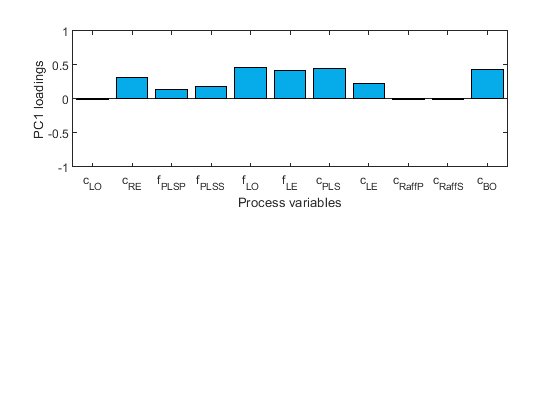

% Create the figure for the 1st principal component
figure()

% Plot the proportion of variance explained
subplot(2,1,1)
bar(measured_variable_labels, PCA_coeff(:,1), 'FaceColor', blue)
ylabel('PC1 loadings')
xlabel('Process variables')
ylim([-1 1])

% Save the current figure
if (SAVE_IMAGES)
    print('fault_detection/output/PCA/PC1_loadings', '-dpng', '-r600')
end